Initially in our project we aimed to build a machine learning model (neural network implementation) to predict the number of calories burned using physical activity data, such as step counts, and active minutes, extracted from a FitBit Data dataset (specifically dailyActivity_merged.csv from [https://github.com/PriyalChotwani/Fitbit-DataAnalysis](https://github.com/PriyalChotwani/Fitbit-DataAnalysis)). Additionally, we wanted to evaluate the model's performance and determine the relative importance of each feature (steps, intensity of activity level, time in each intensity level) in contributing to calorie prediction. This would help in understanding which activities have the most significant impact on calorie burn. The results of the neural network are the following as for model performance data plotting and also the importance of minutes and distances.

First of all the neural network achieved a relatively high accuracy and low mean squered error and R-Squared Error on the test set. Below are the actual results.

- Neural Network Mean Squared Error on Test Set: 0.24852

- Neural Network R-squared on Test Set: 0.70103

- Neural Network Range-Based Percentage Accuracy: 93.5884%

As for the other plots they are generated below. First we attach the Actual vs Predicted Calories Plot.

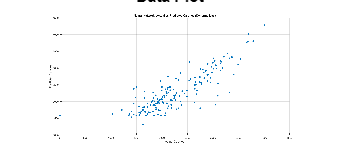

clc;
clear;
imgPath = './images/data_plot.png'; 

img = imread(imgPath);
imshow(img);
title('Data Plot');

Now below is the distances and minutes feature importance plot.

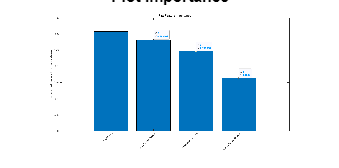


imgPath = './images/plot_mins.png'; 

img = imread(imgPath);
imshow(img);
title('Plot importance');

Afterwards we will also show you the models train-test performance.

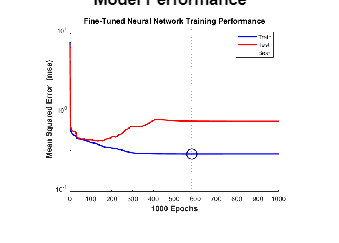


imgPath = './images/model_performance.png'; 
img = imread(imgPath);
imshow(img);
title('Model Performance');

Then, we collected real world data using MATLAB Mobile. This data was used to train a machine learning model that predicts the intensity of the activity.

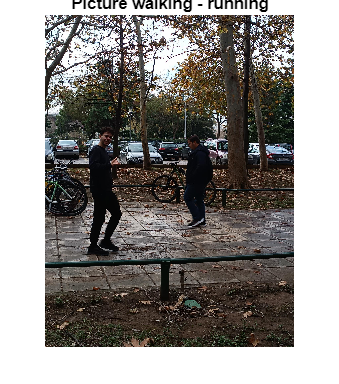


imgPath = './images/testing1.jpeg'; 
img = imread(imgPath);
imshow(img);
title('Picture walking - running');

The data was parsed, and we performed feature engineering. We observed that the most descriptive features for the exercise intensity were the magnitude of the acceleration data, the magnitude of gyroscope data, the GPS speed and the orientation data. We labeled the collected data and performed classification using MATLAB's Classification Learner (session stored in ClassificationLearnerSession.mat). We trained all available classification models and tested them on seperately collected test data. The best-performing model was a Efficient Linear SVM without PCA, which achieved an accuracy of 64.5%. Below are plots of the train data and test data collected, as well as the predicted vs actual labels. 

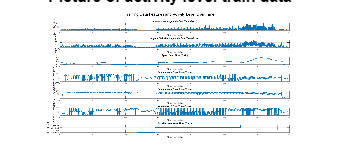


imgPath = './images/activityLevel_trainData.png'; 
img = imread(imgPath);
imshow(img);
title('Picture of activity level train data');

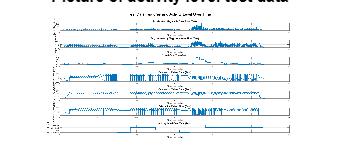


imgPath = './images/activityLevel_testData.png'; 
img = imread(imgPath);
imshow(img);
title('Picture of activity level test data');

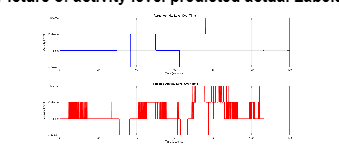


imgPath = './images/activityLevel_predictedvsactualLabels.png'; 
img = imread(imgPath);
imshow(img);
title('Picture of activity level predicted actual Labels');

To count steps, the acceleration data is smoothed with a moving average filter to cut down on noise. Then, peaks are detected using `findpeaks` by setting some thresholds for height and distance between them. The total steps are just the number of peaks found. Also we can see the GPS route that we took in order to gather the data.

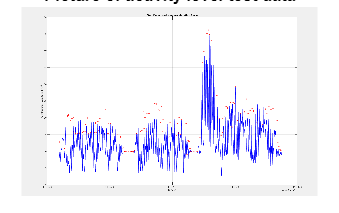

imgPath = './images/step_detection.png'; 
img = imread(imgPath);
imshow(img);
title('Picture of activity level test data');

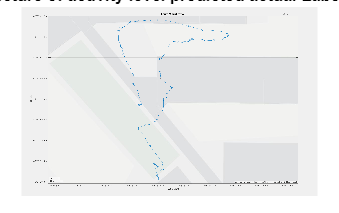


imgPath = './images/gps_route.png'; 
img = imread(imgPath);
imshow(img);
title('Picture of activity level predicted actual Labels');

In the end we merged our code parts into a main.m file that can predict calories based on real data we collected by walking / running with MATLAB Mobile.